# Example 3.2: `Maximum Detection Range of a CW Radar`

Nicholas O'Donoughue 1 July 2019

`We wish to detect the presence of this radar aboard a helicopter, with our detector mounted on another helicopter. Detection of the collision avoidance radar is used as an early warning detection of the approaching threat platform. We assume that both helicopters are airborne at an altitude of h=500 m`

## Solution

`The receiver has a matched 40-MHz bandwidth and a 4-dB noise figure, resulting in a noise level of -124 dBW. If we assume the same detector requirements as in the previous example (`$$P_{\mathrm{D}}=.5$$`, `$$P_{\mathrm{FA}}=10^{-6}$$`, `$$M=10$$`), then the SNR requirement is unchanged (3.66 dB), and we can compute the minimum detectable signals.`

% Detector Design
prob_fa = 0.000001;
prob_d = 0.5;
M = 10;
xi = detector.squareLawMinSNR(prob_fa,prob_d,M)

xi = 3.6515


% Receiver Noise
bw = 40000000;
NF = 5;
N0 = utils.constants.boltzmann*utils.constants.T0*10^(NF/10);
N = 10*log10(N0*bw)

N = -122.9547

`Note that, assuming we sample the signal at the Nyquist rate (twice the signal bandwidth), 10 independent detection samples represent an integration time of `$$10F_s=.16\mu$$`s.`

`In this case, let us assume a receive gain of 10 dBi, representing a moderately directional receiver, and receiver losses of 2 dB.`

Gr=10;
Lr=2;
MDS = xi + N - Gr + Lr

MDS = -127.3033

`Next, we compute the receiver power level and compare to this threshold for mainlobe and sidelobe scenarios.`

% Transmit Parameters
f0 = 35000000000;
Pt_w = 0.035;
Pt = 10*log10(Pt_w); % 35 mW / -14.56 dBW
Gt = 35; % dBi
Lt = 0;
ERP = Pt + Gt - Lt

ERP = 20.4407


SLL = 25; % Sidelobe level (below Gt)
Gt_sidelobe = Gt - SLL;
ERP_sidelobe = ERP - SLL

ERP_sidelobe = -4.5593

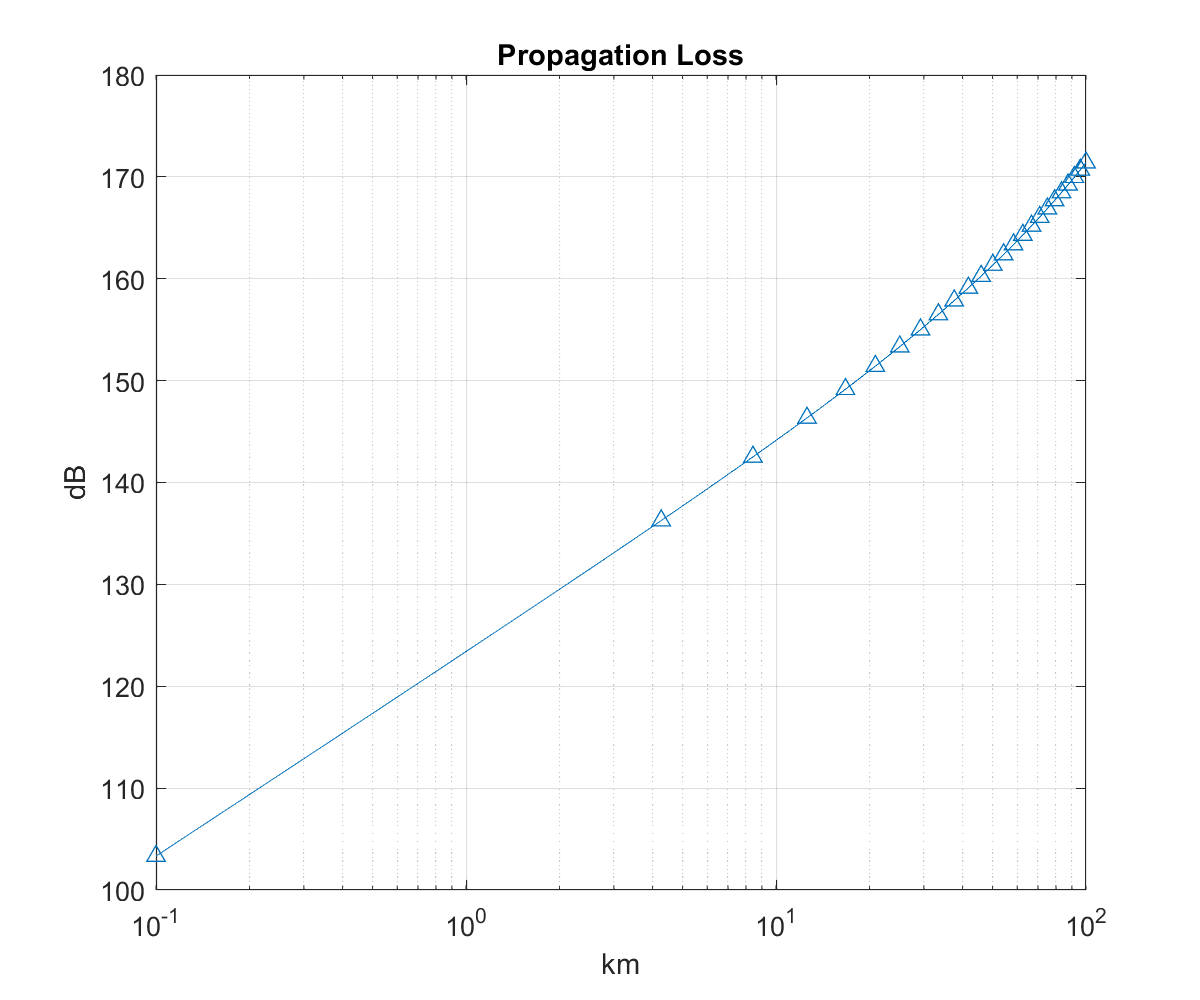


% Propagation
ht = 500;
hr = 500;


% Compute Path Loss
rng_min_km = .1;
rng_max_km = 100;

Rvec = linspace(rng_min_km,rng_max_km,1001)*1e3;
Rvec_coarse = linspace(rng_min_km,rng_max_km,25)*1e3;

Lprop = prop.pathLoss(Rvec,f0,ht,hr,true,[]);
Lprop_coarse = prop.pathLoss(Rvec_coarse,f0,ht,hr,true,[]);

figure;
hdl=plot(Rvec/1e3,Lprop);
hold on;
plot(Rvec_coarse/1e3,Lprop_coarse,'^','Color',hdl.Color);
ylabel('dB');
xlabel('km');
title('Propagation Loss');
grid on;
set(gca,'xscale','log')

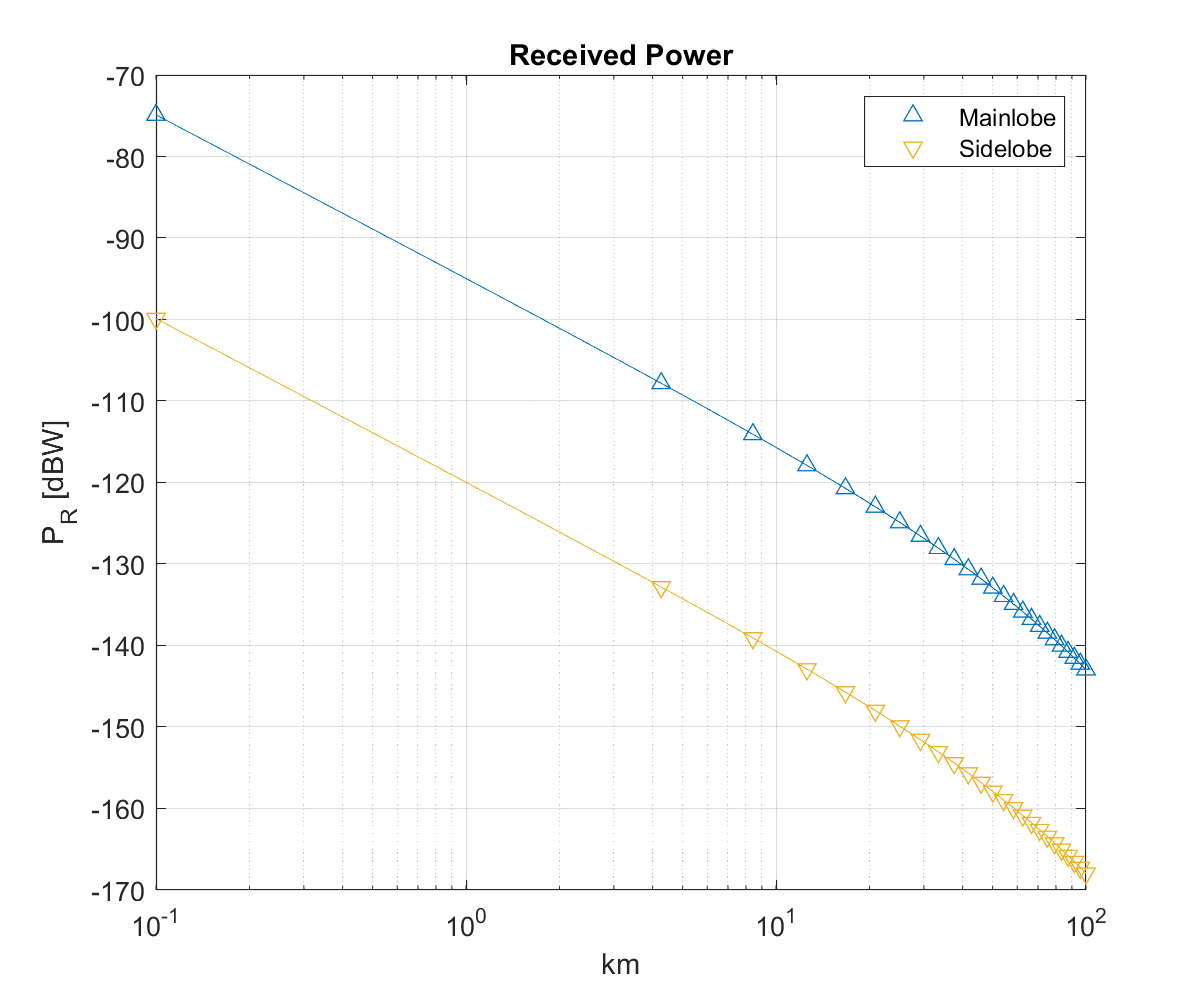


% Compute Received Power
Pr = ERP + Gr-Lr-Lprop;
Pr_sl = Pr - SLL;
Pr_coarse = ERP + Gr-Lr-Lprop_coarse;
Pr_sl_coarse = Pr_coarse - SLL;

figure;
hdl=plot(Rvec/1e3,Pr);
hold on;
utils.excludeFromLegend(hdl);
plot(Rvec_coarse/1e3,Pr_coarse,'^','Color',hdl.Color,'DisplayName','Mainlobe');
hdl=plot(Rvec/1e3,Pr_sl);
utils.excludeFromLegend(hdl);
plot(Rvec_coarse/1e3,Pr_sl_coarse,'v','Color',hdl.Color,'DisplayName','Sidelobe');
ylabel('P_R [dBW]');
xlabel('km');
title('Received Power');
legend('Location','NorthEast')
grid on;
set(gca,'xscale','log')

`Note that, given the height of the transmitter and receiver, free-space path loss is in effect.  The atmospheric loss at 35 GHz occurs at a rate of 0.11 dB/km. Mainlobe detection occurs at a range of 13.9 km, while sidelobe detection occurs at a range of 923m. Compare these numbers to the radar's operational range of 900m\cite{richards2010principles}. Based on these numbers, it is possible to detect the mainlobe of the radar's emissions far before it can detect the ownship's presence (10.3 km versus 900m), but detection of the radar's sidelobe pulses will occur shortly before the radar has a chance to detect the EW receiver's platform.\footnote{The radio horizon for these transmitters is 160 km, so it does not affect detection range in this example.}`

% Desired Detection Performance
Pr_min = N + xi;

% Find expected max det range, for plotting
R_soln = detector.squareLawMaxRange(prob_fa,prob_d,M,f0,ht,hr,ERP+Gr-Lr-N,true,[])

R_soln = 1.4525e+04

R_sl_soln = detector.squareLawMaxRange(prob_fa,prob_d,M,f0,ht,hr,ERP_sidelobe+Gr-Lr-N,true,[])

R_sl_soln = 926.8283

`Next, we conduct a Monte Carlo verification of the predicted detection range for mainlobe and sidelobe detection.`

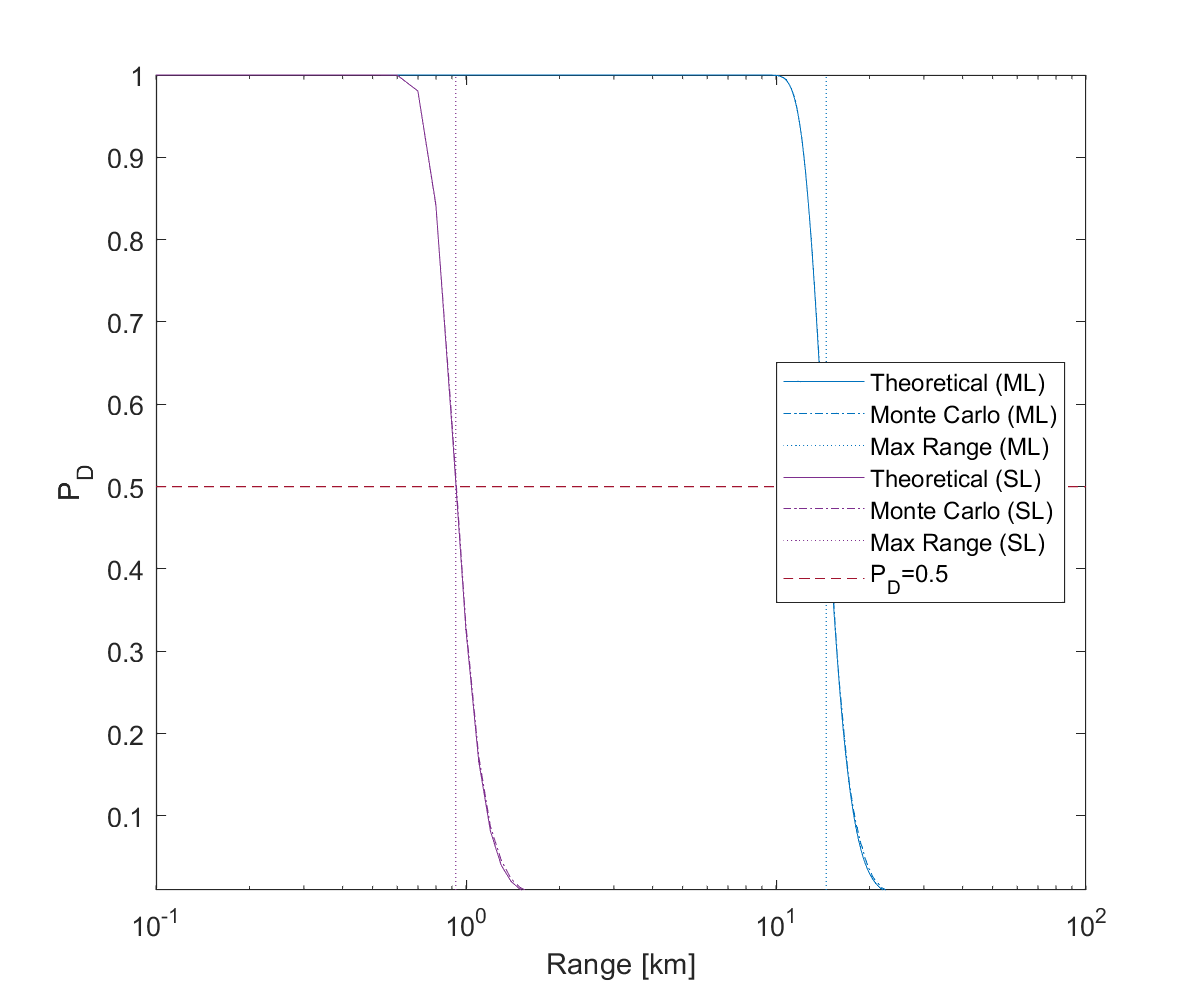

nMC = 1e4;

%  At each range, compute the received
%  power level.  Conduct a monte carlo trial
%  at each power level to compute PD and compare
%  to the desired threshold.

% Check for existence of Statistics & Machine Learning Toolbox
use_stat_toolbox = license('test','Statistics_Toolbox');
   % If TRUE, then built-in functions will be used.
   % If FALSE, then custom-builts replacements in the utils namespace will
   % be used.
   
% Convert noise and signal power to linear units
Nlin = 10.^(N/10);
Pr_lin = 10.^(Pr/10);
Pr_sl_lin = 10.^(Pr_sl/10);

xi = Pr-N;
xi_lin = 10.^(xi/10);
xi_sl = Pr_sl-N;
xi_sl_lin = 10.^(xi_sl/10);

% Theoretical Result
if use_stat_toolbox
    eta = chi2inv(1-prob_fa,2*M);
    probD_theo = 1-ncx2cdf(eta,2*M,2*M.*xi_lin);
    probD_sl_theo = 1-ncx2cdf(eta,2*M,2*M.*xi_sl_lin);
else
    eta = utils.chi2inv(1-prob_fa,2*M);
    probD_theo = 1-utils.ncx2cdf(eta,2*M,2*M.*xi_lin);
    probD_sl_theo = 1-utils.ncx2cdf(eta,2*M,2*M.*xi_sl_lin);
end

% Generate noise and signal vectors
n = sqrt(Nlin/2) * (randn(M,nMC) + 1i*randn(M,nMC)); % Complex Gaussian with variance of N
start_phase = 2*pi*rand(1,nMC);
pulse = exp(1i*2*pi*(0:M-1)/10); % Unit Power
s = pulse(:).*exp(1i*start_phase);

% Compute Sufficient Statistic
probD = zeros(size(Pr_lin));
probD_sl = zeros(size(Pr_lin));
for rngidx = 1:numel(Pr_lin)
    % Scale signal power
    thisS = sqrt(Pr_lin(rngidx))*s;
    thisS_sl = sqrt(Pr_sl_lin(rngidx))*s;
    
    % Run Energy Detector
    detResult = detector.squareLaw(n+thisS,Nlin/2,prob_fa);
    detResult_sl = detector.squareLaw(n+thisS_sl,Nlin/2,prob_fa);
    
    % Count detections
    probD(rngidx) = sum(detResult)/nMC;
    probD_sl(rngidx) = sum(detResult_sl)/nMC;
end


fig=figure;
hdl=plot(Rvec/1e3,probD_theo,'DisplayName','Theoretical (ML)');
hold on;
plot(Rvec/1e3,probD,'-.','Color',hdl.Color,'DisplayName','Monte Carlo (ML)');
plot(R_soln/1e3*[1 1],[0 1],':','Color',hdl.Color,'DisplayName','Max Range (ML)');

hdl=plot(Rvec/1e3,probD_sl_theo,'DisplayName','Theoretical (SL)');
plot(Rvec/1e3,probD_sl,'-.','Color',hdl.Color,'DisplayName','Monte Carlo (SL)');
plot(R_sl_soln/1e3*[1 1],[0 1],':','Color',hdl.Color,'DisplayName','Max Range (SL)');

plot(Rvec_coarse/1e3,prob_d*ones(size(Rvec_coarse)),'--','DisplayName','P_D=0.5');

xlabel('Range [km]');
ylabel('P_D');
set(gca,'xscale','log');
ylim([.01,1]);
legend('Location','East');